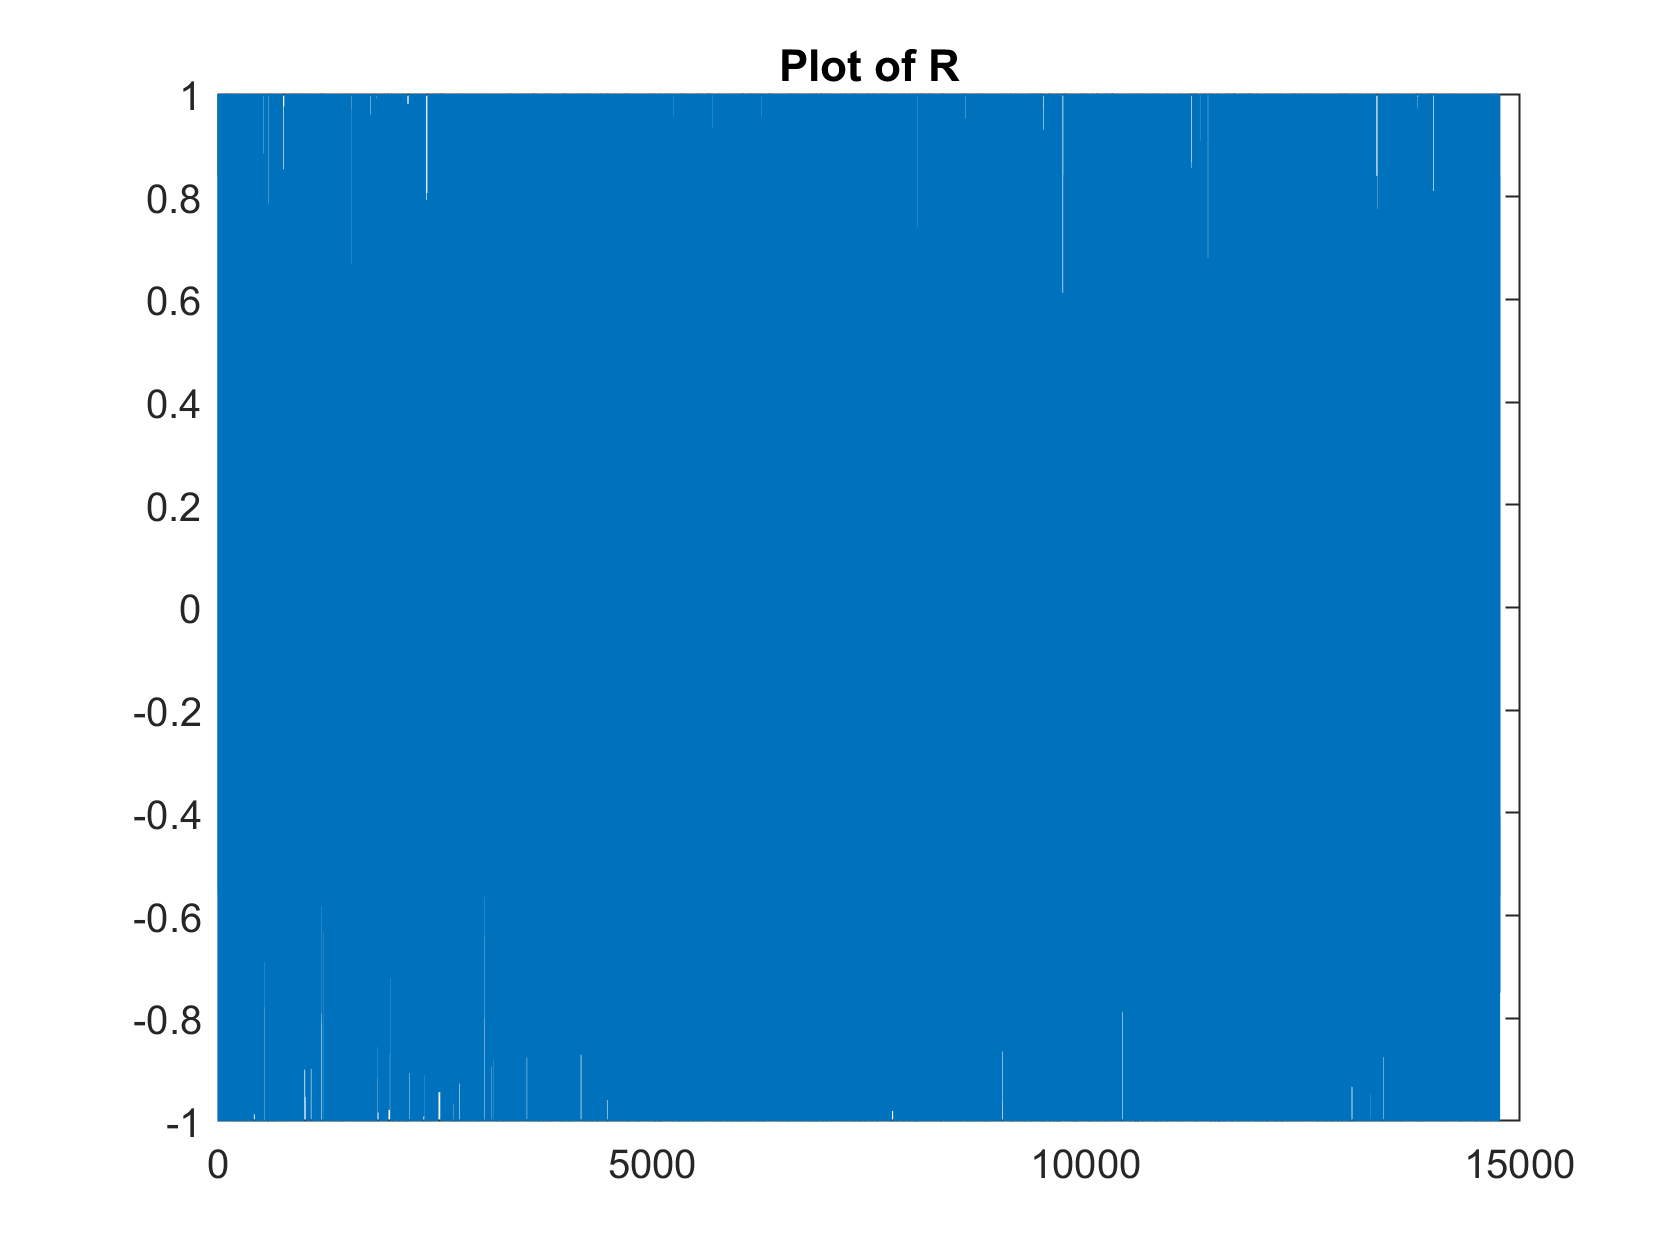

[r,fs] = audioread('C:\Users\13104\Documents\EE432\Labs\Lab 10\newwav.wav');
Tb = 0.1; %10 bits per second
Ns = 400; %Number of samples per bit
fc = 500; %Center Frequency is 500Hz
df = 10;
x = linspace(0,Tb,Ns);
f0 = fc-df; %490 Hz
f1 = fc+df; %510 Hz
s0 = sin(2*pi*f0*x);%logic 0 signal
s1 = sin(2*pi*f1*x); %logic 1 signal
plot(r)
title("Plot of R")

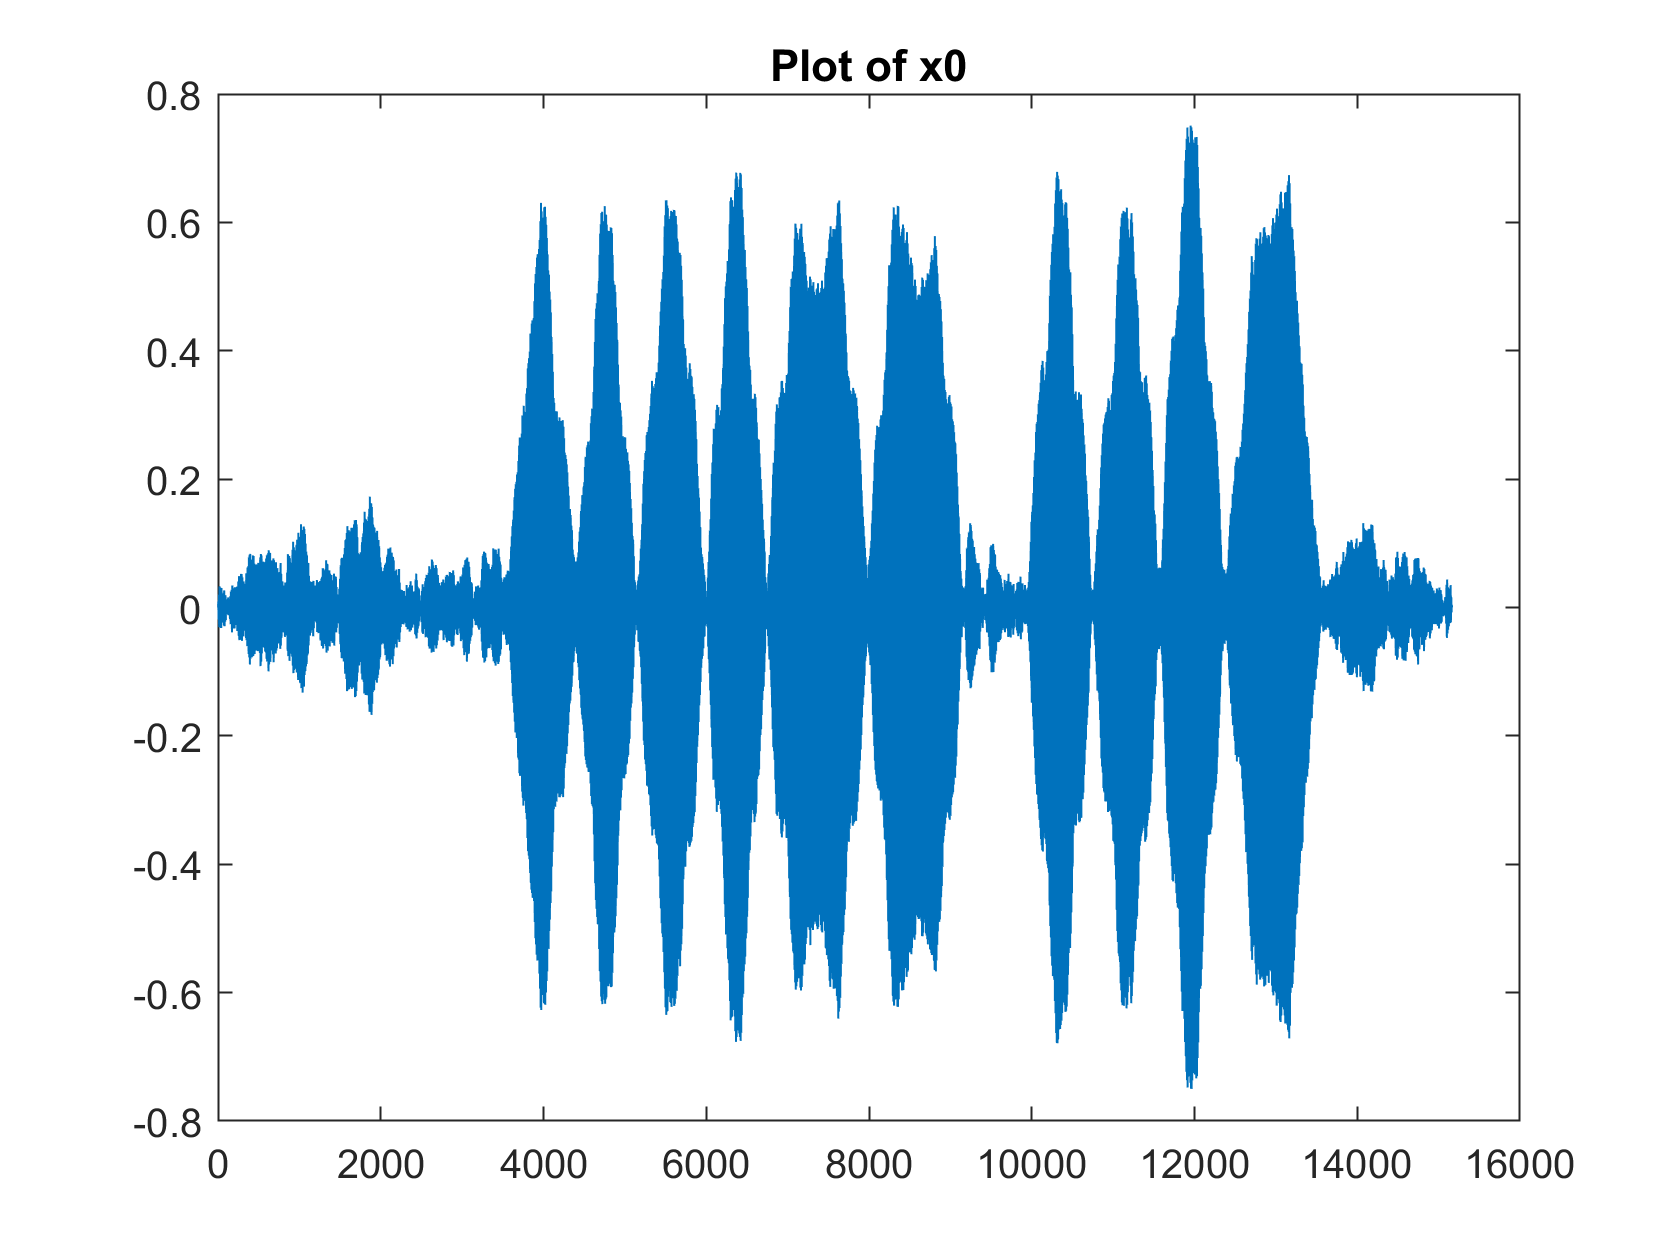


%sound(r,4000);

%Receiver
%Matched Filter Design
x0 = (2/Ns)*conv(r, s0);
plot(x0)
title("Plot of x0")

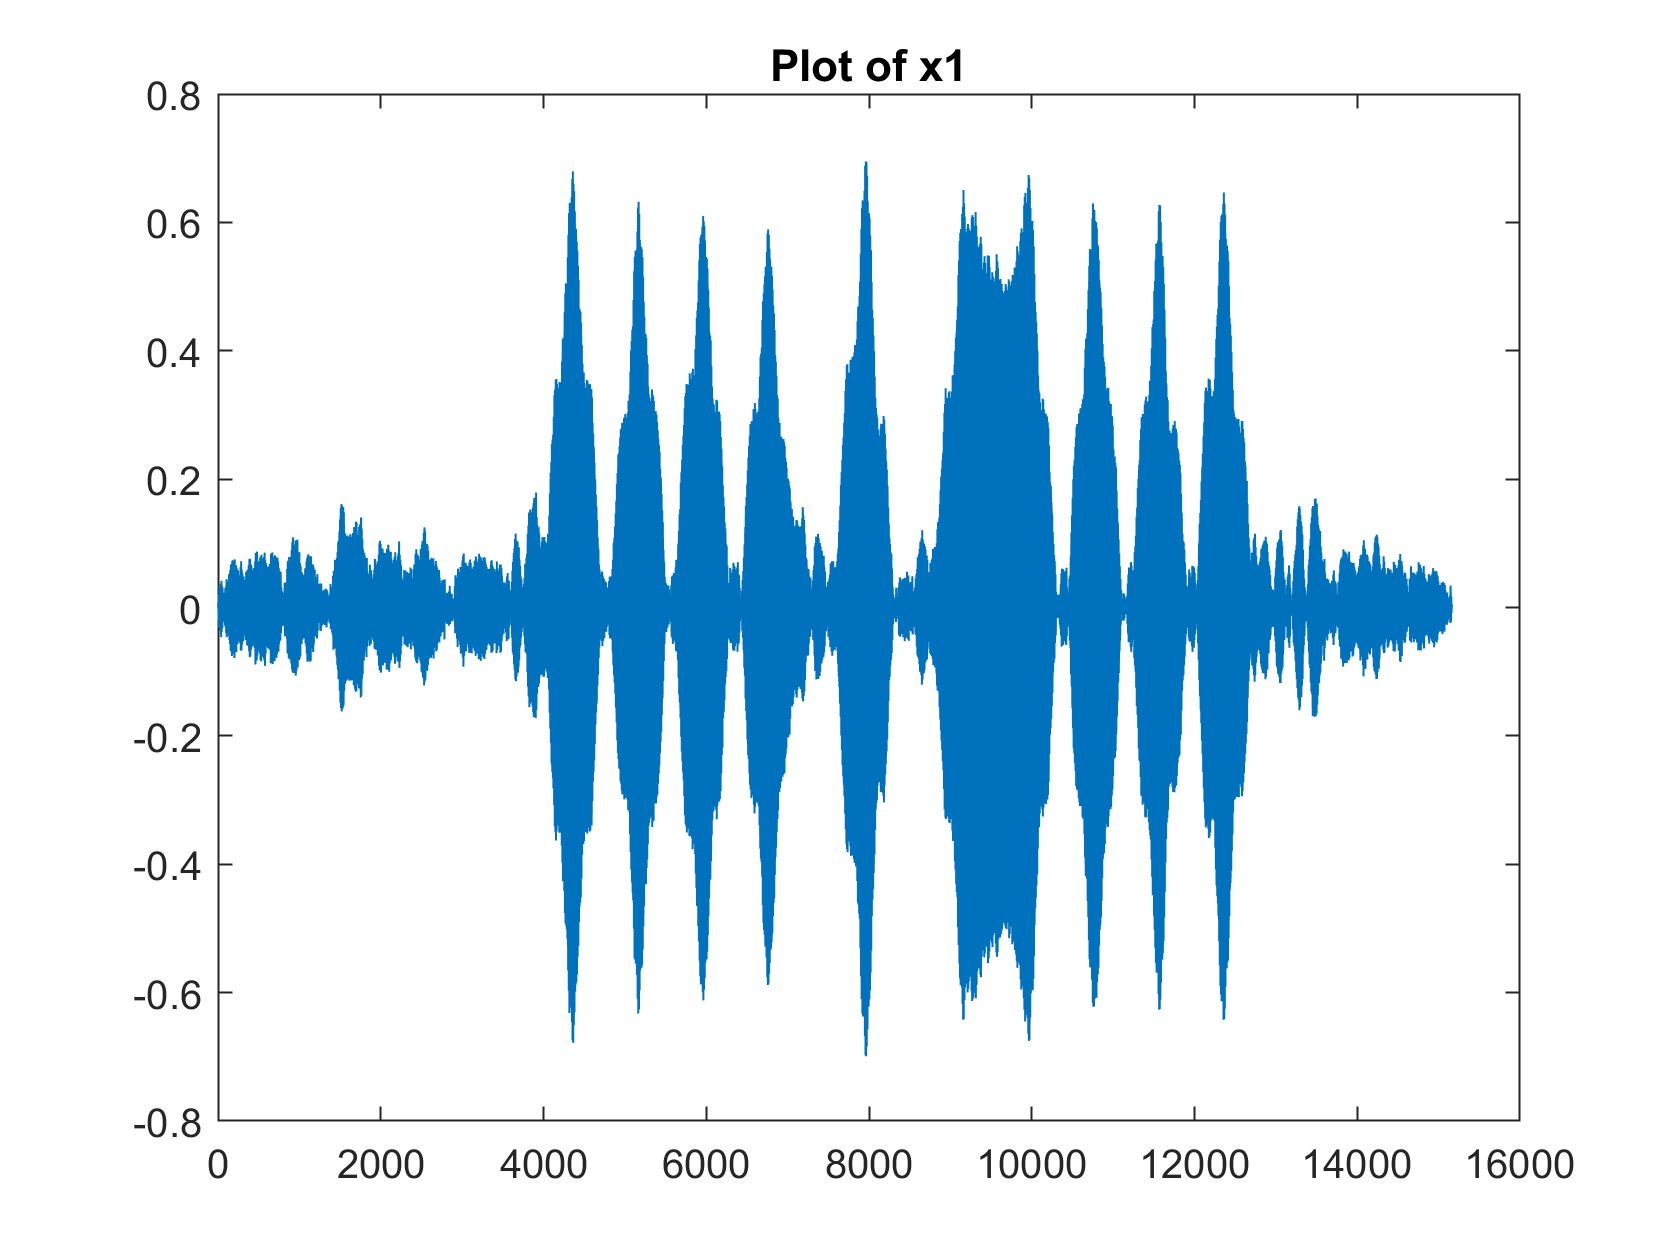

x1 = (2/Ns)*conv(r, s1);
plot(x1)
title("Plot of x1")

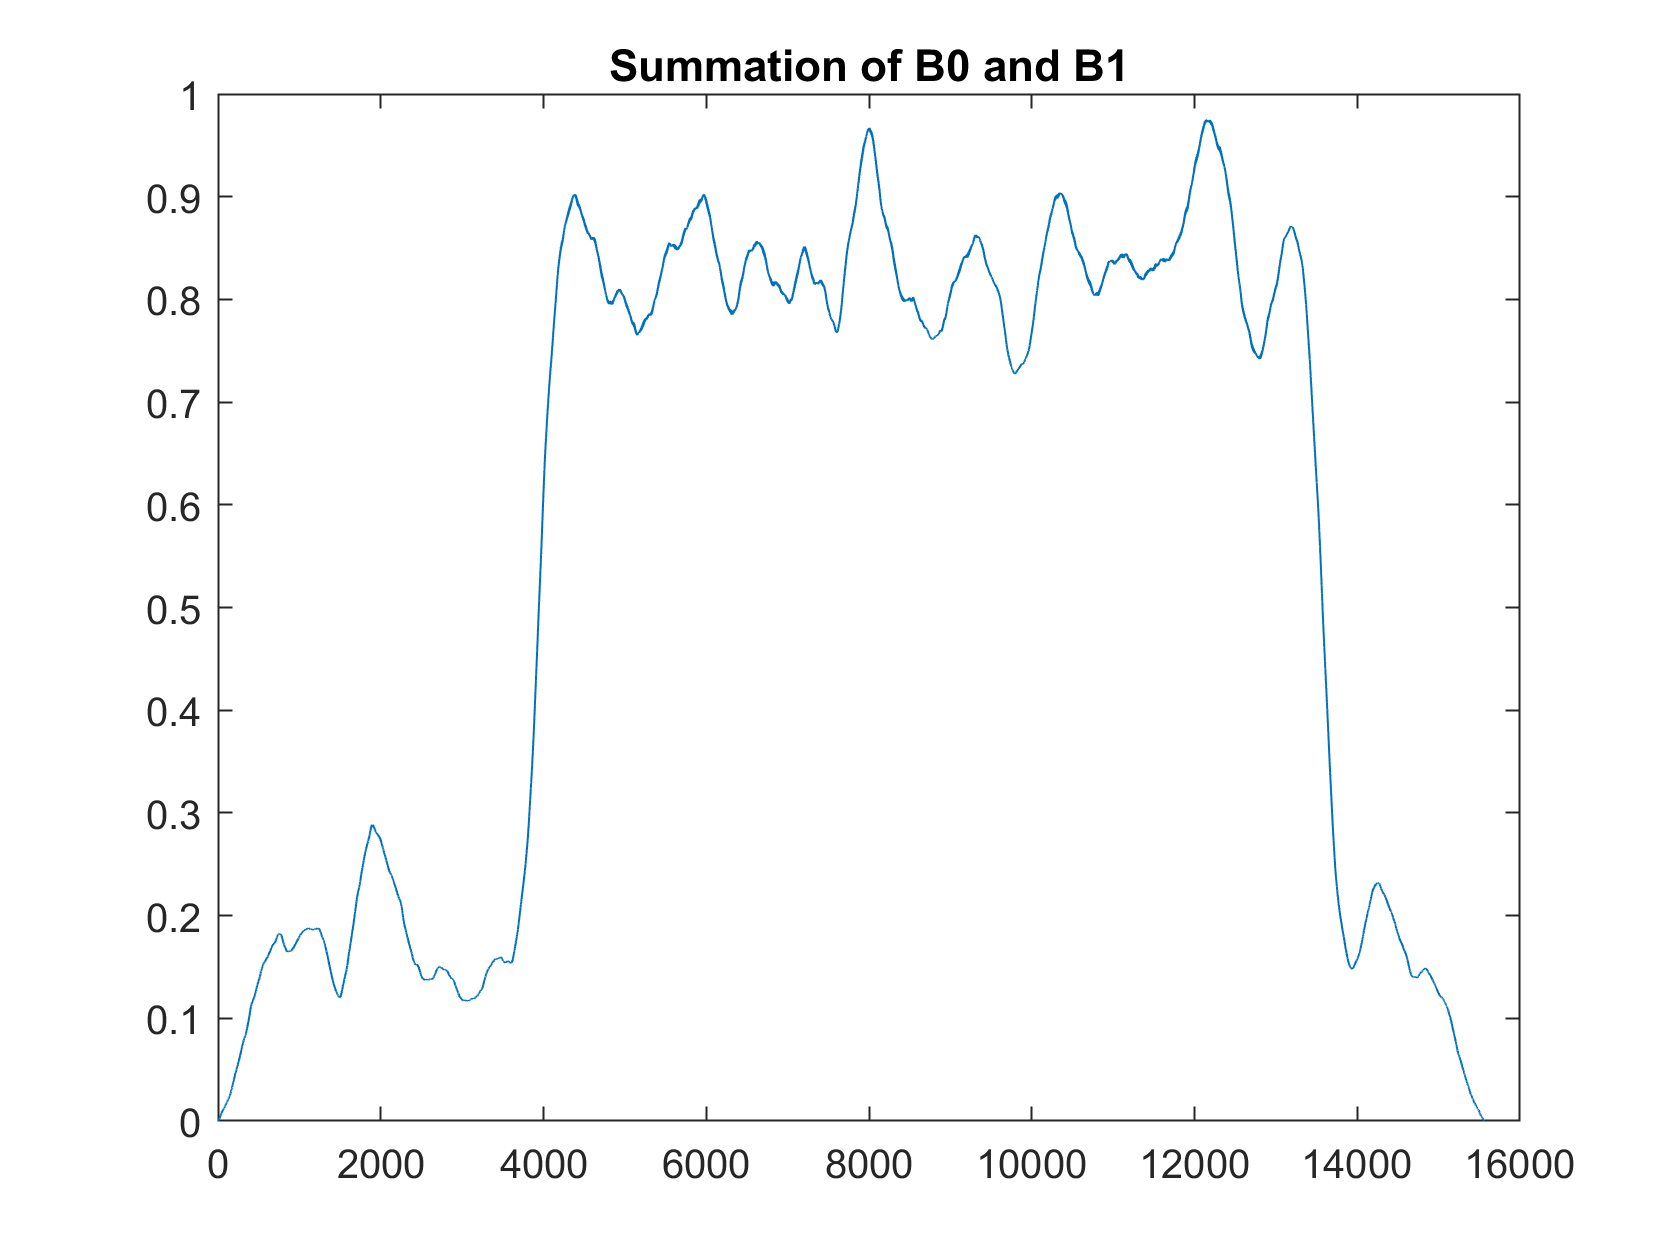


%Envelope Detector
%rectify each signal 
x0 = abs(x0);
x1 = abs(x1);
%LPF
b0 = conv(x0, (2/Ns)*ones(1,Ns));
b1 = conv(x1, (2/Ns)*ones(1,Ns));

%Summation of these sequences
b_gammaselector = b1+b0;
plot(b_gammaselector)
title('Summation of B0 and B1')

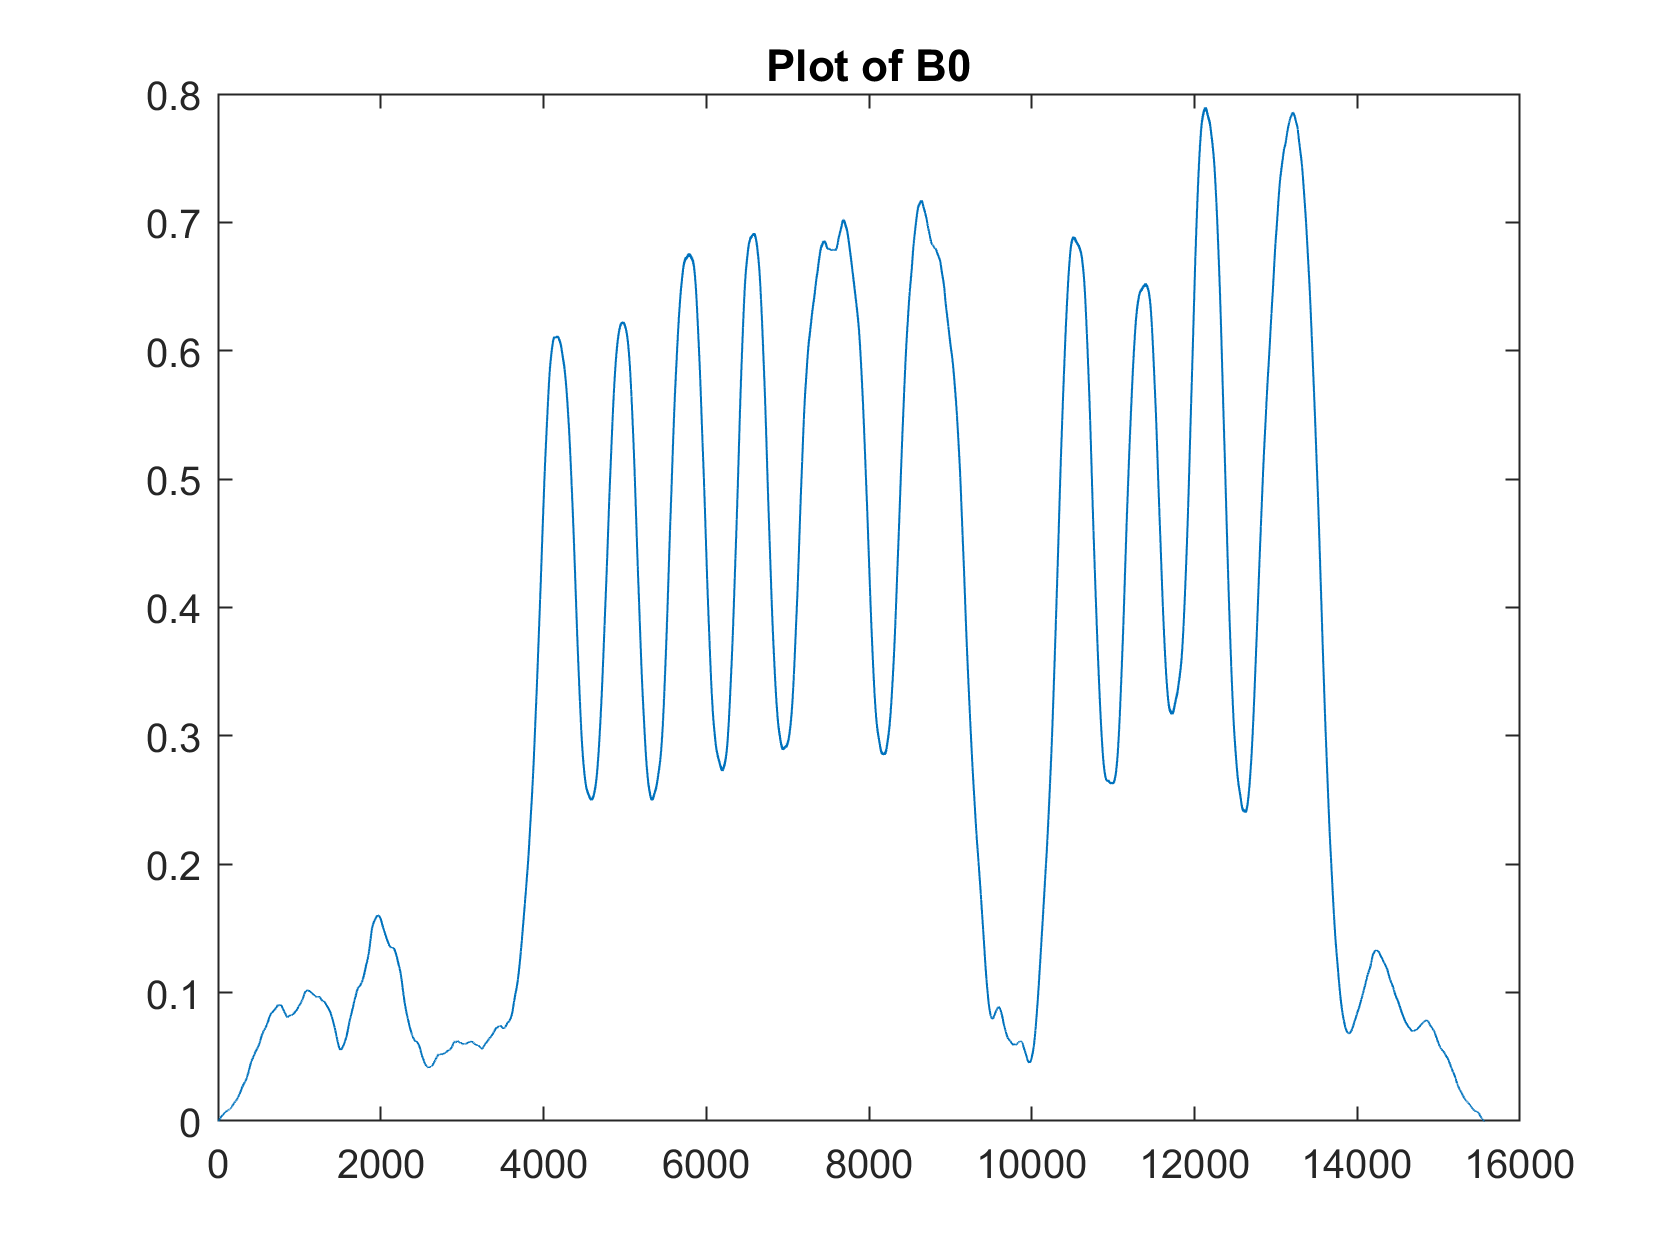

plot(b0)
title("Plot of B0")

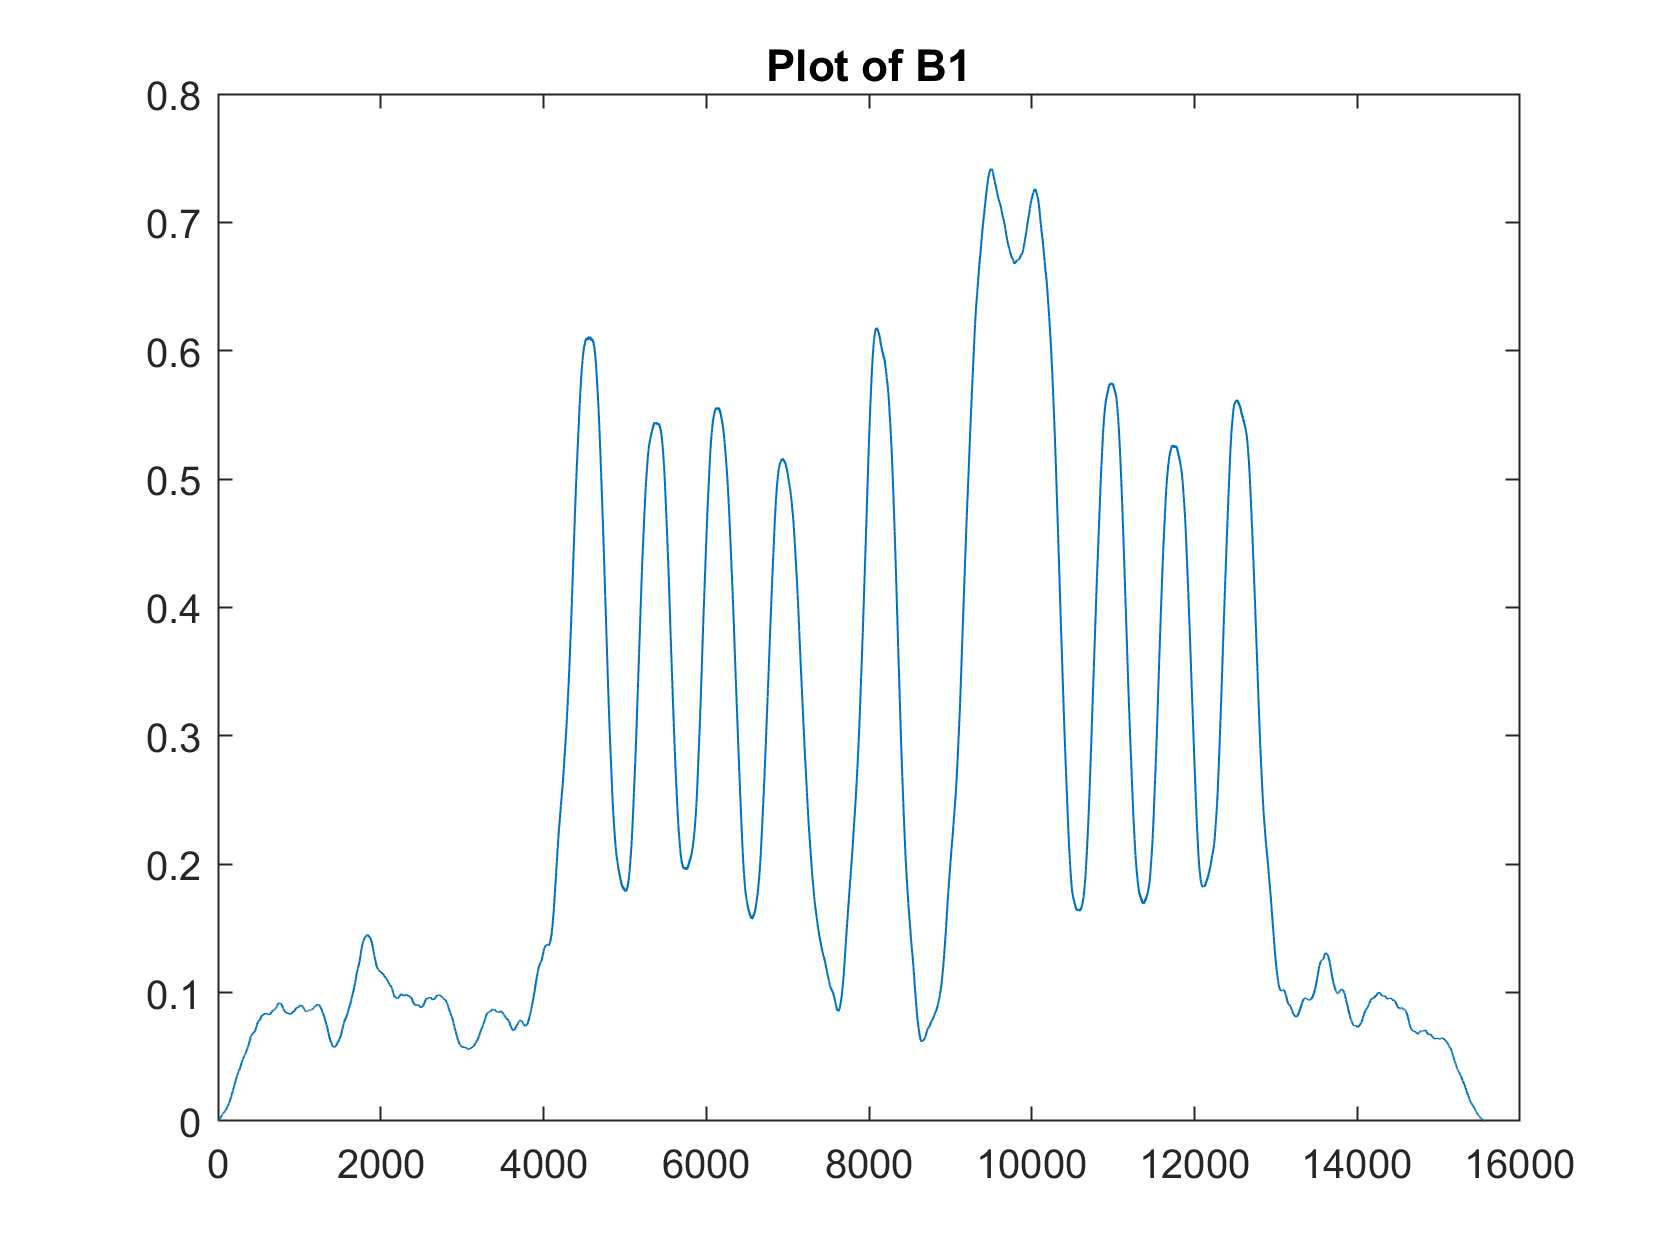

b0 = (-1*b0);

plot(b1)
title("Plot of B1")

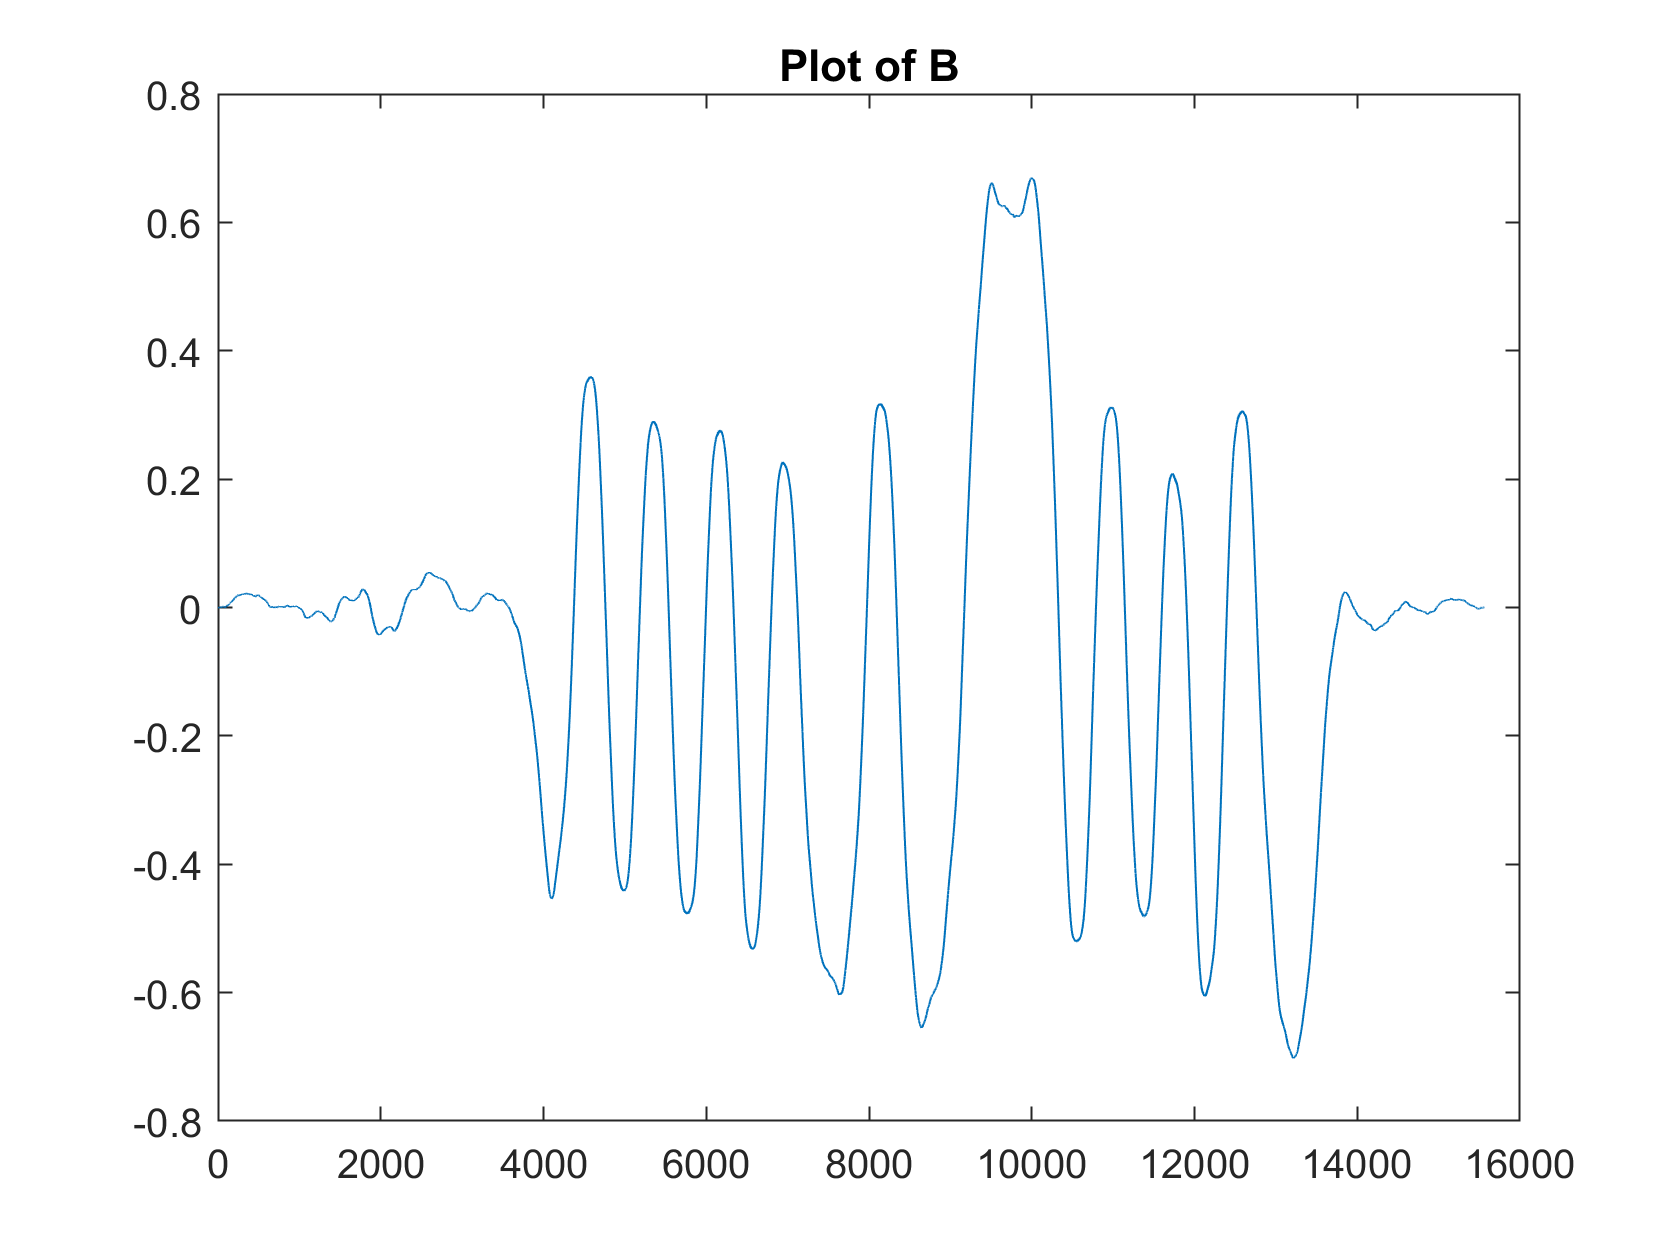

b = b0 + b1;
plot(b)
title("Plot of B")


%Find gamma
gamma = .4 %I just chose this because it was close

gamma = 0.4000

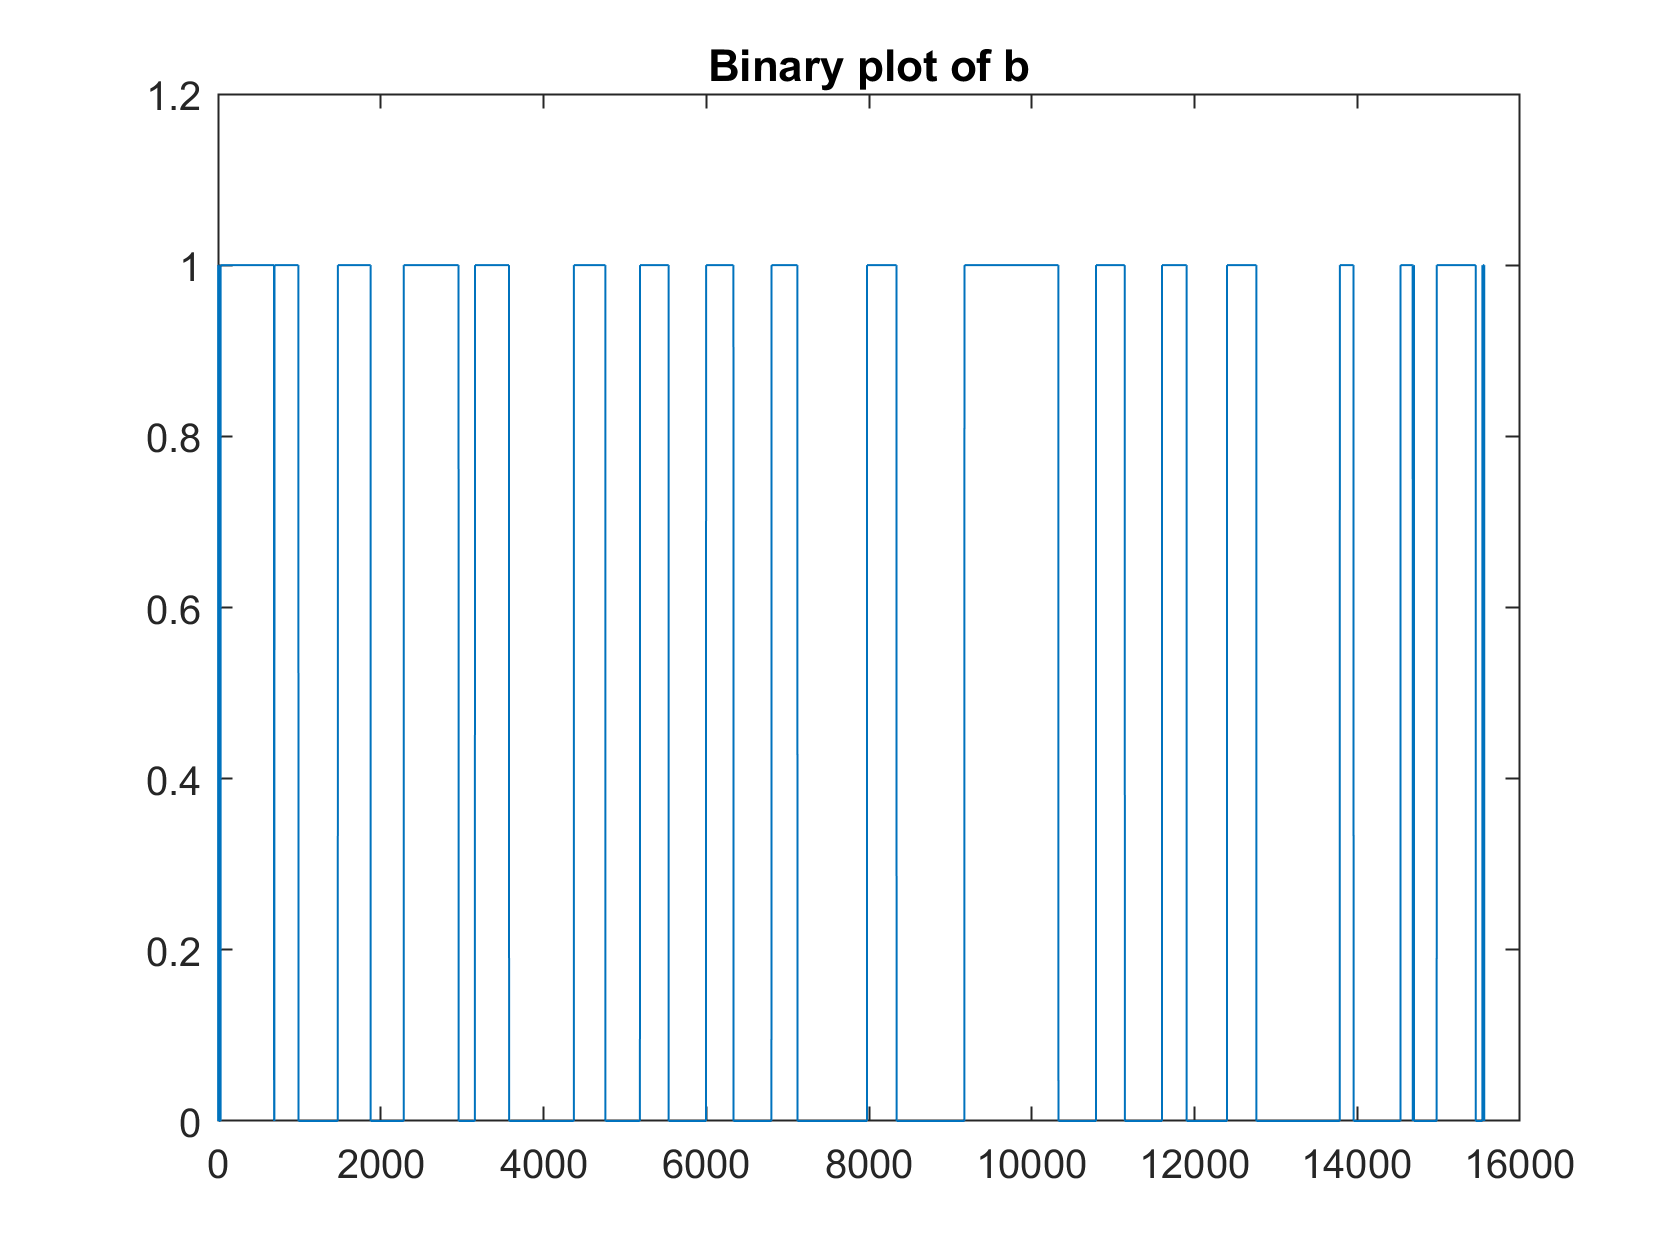

% %to the first peak of actual data lol

%Sign and level shifter
bhat = zeros(1, length(b));
for i = 1:length(b)
    if (b(i) > 0)
        bhat(i) = 1;
    elseif (b(i) == 0)
        bhat(i) = 0;
    else 
        bhat(i) = 0;
    end
end
bhat;
plot(bhat)
axis([0 16000 0 1.2])
title ('Binary plot of b')


%Bit Synchronization
tzero = findt0(b1, b0, gamma)

tzero = 4038

[y, I] = max(b0(tzero:tzero+Ns))

y = -0.3406

I = 401

ts = I + tzero -1

ts = 4438


%Populating synch array 
synch = zeros(1,8); 
for i = 0:7
    synch(i+1) = b(ts)+(Ns*i); 
end
synch;

test = [];
for k = -1:6
    test = [test b(ts + k*Ns)];
end
test

test =    -0.4012    0.2081   -0.2640    0.1622   -0.3418    0.1294   -0.3726    0.1061



test_d = zeros(1, length(test));
for i = 1:length(test)
    if (test(i) > 0)
        test_d(i) = 1;
    elseif (test(i) == 0)
        test_d(i) = 0;
    else 
        test_d(i) = 0;
    end
end
test_d

test_d =      0     1     0     1     0     1     0     1



%Assigning Data
data = [];
for k = 7:22 %before this 0-7 are sync bits
    data = [data b(ts + k*Ns)];
end
data

data =    -0.3333   -0.6036    0.2141   -0.3542   -0.5880    0.2080    0.6249    0.6605   -0.3977    0.1570   -0.3245    0.1102   -0.5008    0.1395   -0.2446   -0.6994



%Now we want to convert this thing into 1's and 0's 
binary_data = zeros(1, length(data));
for i = 1:length(data)
    if (data(i) > 0)
        binary_data(i) = 1;
    elseif (data(i) == 0)
        binary_data(i) = 0;
    else 
        binary_data(i) = 0;
    end
end
binary_data

binary_data =      0     0     1     0     0     1     1     1     0     1     0     1     0     1     0     0


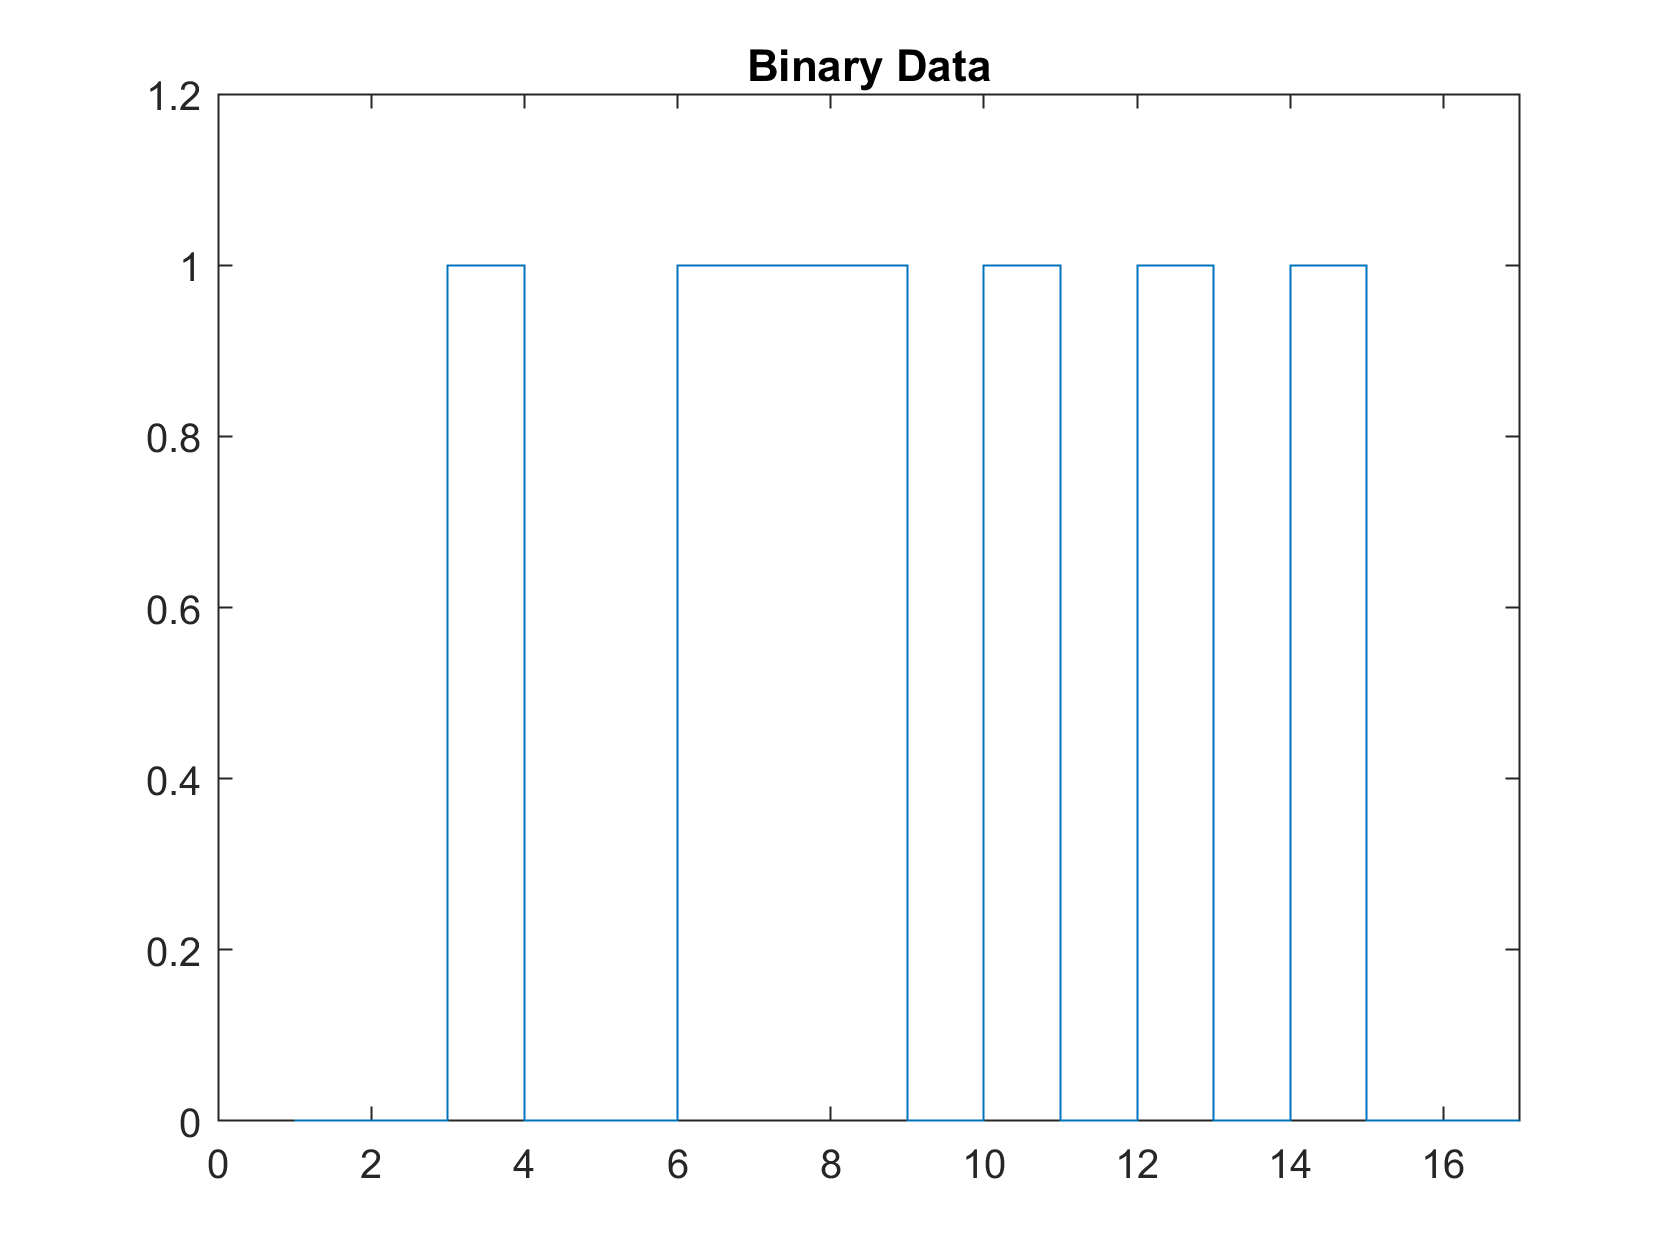

figure;
stairs([binary_data,binary_data(end)]);
axis([0 17 0 1.2])
title('Binary Data')

function t0 = findt0(b1, b0, gamma)
%Bit Synchronization
t0 = 1;
while(abs(b1(t0) + b0(t0))< gamma)
    t0 = t0 +1; 
end
end
